% =========================================================================
% aocs_hybrid_model.m
%
% reaction wheel + rcs desaturation model for spacecraft attitude control
%
% purpose:
%   builds a physically consistent model of reaction wheel momentum
%   buildup and rcs-based desaturation using spacecraft attitude history
%   from R_SC rotation matrices. outputs wheel momentum history,
%   saturation/desaturation events, hydrazine budget, and a ranked
%   top-15 slew maneuver table.
%
% fixes applied:
%   - plots slew angle over mission time
%
% data file required:
%   angle_data.mat
%
% expected variables:
%   R_SC
%   theta_SP
%   thrust_vector
%
% optional variables:
%   thrust
%   position
% =========================================================================

clear;
clc;
close all;

% =========================================================================
% section 1 — load data file and extract variables
% =========================================================================

data = load('angle_data.mat');

% spacecraft attitude history: N x 3 x 3 rotation matrices
R_SC = data.R_SC;

% steering law commanded pointing profile
theta_SP = data.theta_SP;

% effective thrust direction history
thrust_vector = data.thrust_vector;

% optional variables
if isfield(data,'thrust')
    thrust = data.thrust;
end

if isfield(data,'position')
    position = data.position;
end

% number of timesteps
N = size(R_SC,1);

% =========================================================================
% section 2 — mission and hardware parameters
% =========================================================================

% total mission duration [years]
mission_years = 16.79;

% total mission duration [s]
T_total = mission_years * 365.25 * 24 * 3600;

% timestep derived from R_SC sampling
delta_t = T_total / (N-1);

% spacecraft inertia tensor [kg*m^2]
%
% configuration : deployed solar panels
%
% moments of inertia:
%
% Lxx = 16912.28
% Lyy = 2610.23
% Lzz = 14892.69
%
% Lxz = 2.42
% Lyz = 0.68

I_body = [ ...
    16912.28,     0.00,     2.42 ;
        0.00,  2610.23,     0.68 ;
        2.42,     0.68, 14892.69 ];

% reaction wheel saturation limit [N*m*s]
RW_H_sat = 50;

% residual wheel momentum after desaturation [N*m*s]
RW_H_target = 10;

% propulsion parameters
Isp = 220;
g0  = 9.80665;

% deadband threshold [rad]
theta_deadband = deg2rad(5);

% minimum slew threshold [rad]
theta_min = theta_deadband;

% maximum number of consecutive steps allowed in one slew event
% prevents continuous cruise tracking from becoming one giant slew
max_event_steps = 1;

% =========================================================================
% section 3 — identify invalid timesteps
%
% timesteps containing NaNs are treated as blackout periods.
% wheel momentum is held constant through blackout windows.
% =========================================================================

valid_k = true(N,1);
for k = 1:N
    if any(isnan(R_SC(k,:,:)),'all')
        valid_k(k) = false;
    end
end

n_invalid = sum(~valid_k);

fprintf('detected %d invalid timesteps\n', n_invalid);

detected 169 invalid timesteps


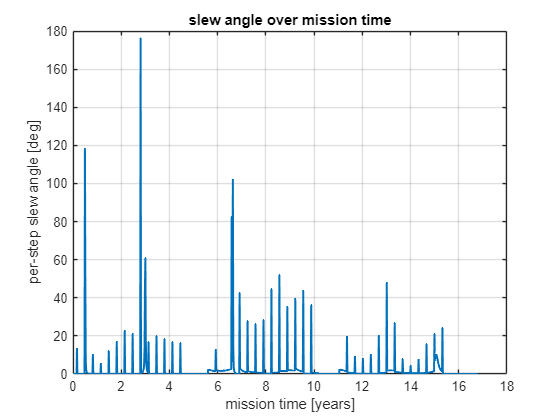


% =========================================================================
% section 4 — relative attitude propagation
%
% for each consecutive valid pair:
%
%   DeltaR_k  = R_SC(k)^T * R_SC(k+1)
%   theta_k   = acos( (trace(DeltaR_k)-1)/2 )
%   a_hat_k   = extracted rotation axis
%   omega_k   = angular velocity vector
%   H_body_k  = spacecraft angular momentum
% =========================================================================

theta_k    = zeros(N-1,1);
a_hat_k    = zeros(N-1,3);
omega_k    = zeros(N-1,3);
H_body_k   = zeros(N-1,3);

step_valid = false(N-1,1);

for k = 1:N-1

    % skip blackout intervals
    if ~valid_k(k) || ~valid_k(k+1)

        a_hat_k(k,:) = [0 0 1];
        continue;

    end

    step_valid(k) = true;

    % extract rotation matrices
    R_k  = squeeze(R_SC(k,:,:));
    R_k1 = squeeze(R_SC(k+1,:,:));

    % ---------------------------------------------------------------------
    % equation 1 — relative rotation matrix
    % ---------------------------------------------------------------------

    DeltaR = R_k' * R_k1;

    % ---------------------------------------------------------------------
    % equation 2 — rotation angle
    % ---------------------------------------------------------------------

    c = (trace(DeltaR)-1)/2;

    % numerical protection
    c = max(-1,min(1,c));

    theta_k(k) = acos(c);

    % ---------------------------------------------------------------------
    % equation 3 — rotation axis
    % ---------------------------------------------------------------------

    s = sin(theta_k(k));

    if abs(s) > 1e-8

        axis_vec = [ ...
            DeltaR(3,2)-DeltaR(2,3);
            DeltaR(1,3)-DeltaR(3,1);
            DeltaR(2,1)-DeltaR(1,2)];

        axis_vec = axis_vec ./ (2*s);

        if norm(axis_vec) > 1e-12
            axis_vec = axis_vec ./ norm(axis_vec);
        else
            axis_vec = [0;0;1];
        end

    else

        axis_vec = [0;0;1];

    end

    a_hat_k(k,:) = axis_vec';

    % ---------------------------------------------------------------------
    % equation 4 — angular velocity
    % ---------------------------------------------------------------------

    omega_k(k,:) = (theta_k(k)/delta_t) .* axis_vec';

    % ---------------------------------------------------------------------
    % equation 5 — body angular momentum
    % ---------------------------------------------------------------------

    H_body_k(k,:) = (I_body * omega_k(k,:)')';

end

% =========================================================================
% section 5 — reaction wheel momentum propagation
%
% reaction wheel momentum accumulates spacecraft angular momentum.
%
% wheel saturation occurs when:
%
%   norm(H_RW) >= RW_H_sat
%
% during desaturation:
%   - momentum magnitude reduced to RW_H_target
%   - direction preserved
%   - hydrazine consumption computed
% =========================================================================

% reaction wheel momentum history
H_RW = zeros(N,3);

% saturation flag
sat_flag = zeros(N,1);

% desaturation bookkeeping
desat_count = 0;

m_RCS_vec   = [];
desat_times = [];

% wheel engagement tracking
deadband_active = false(N-1,1);

for k = 1:N-1

    % ---------------------------------------------------------------------
    % wheel control law
    % ---------------------------------------------------------------------

    if theta_k(k) > theta_deadband

        deadband_active(k) = true;

        H_RW(k+1,:) = H_RW(k,:) + H_body_k(k,:) .* delta_t;

    else

        H_RW(k+1,:) = H_RW(k,:);

    end

    % ---------------------------------------------------------------------
    % saturation check
    % ---------------------------------------------------------------------

    H_norm = norm(H_RW(k+1,:));

    if H_norm >= RW_H_sat

        sat_flag(k+1) = 1;

        desat_count = desat_count + 1;

        H_pre = H_RW(k+1,:);

        % -----------------------------------------------------------------
        % equation 8 — desaturation
        % -----------------------------------------------------------------

        if H_norm > 1e-12

            H_post = H_pre .* (RW_H_target / H_norm);

        else

            H_post = zeros(1,3);

        end

        DeltaH_RCS = H_pre - H_post;

        % -----------------------------------------------------------------
        % equation 9 — hydrazine usage
        % -----------------------------------------------------------------

        m_k = norm(DeltaH_RCS) / (Isp * g0);

        m_RCS_vec(end+1,1)   = m_k;
        desat_times(end+1,1) = k+1;

        % update wheel state
        H_RW(k+1,:) = H_post;

    end

end

% =========================================================================
% section 6 — mission statistics
% =========================================================================

H_RW_mag = vecnorm(H_RW,2,2);

peak_momentum = max(H_RW_mag);

total_hydrazine = sum(m_RCS_vec);

% =========================================================================
% section 7 — slew event identification
%
% a slew event exists when:
%
%   theta_k > theta_min
%
% consecutive valid steps are clustered into a single maneuver event.
%
% IMPORTANT:
%   total slew angle is computed using NET relative rotation between
%   event start and end attitudes — NOT cumulative path length.
% =========================================================================

is_slew = (theta_k > theta_min) & step_valid;

maneuver_events = struct( ...
    'start_step',{}, ...
    'end_step',{}, ...
    'start_time',{}, ...
    'end_time',{}, ...
    'total_angle',{}, ...
    'mean_axis',{}, ...
    'had_desat',{}, ...
    'hydrazine',{});

event_count = 0;

in_event = false;

for k = 1:N-1

    if is_slew(k) && ~in_event

        in_event = true;
        event_start = k;

    end

    should_close = false;

    if in_event

        if ~is_slew(k)
            should_close = true;
        end

        if (k - event_start) >= max_event_steps
            should_close = true;
        end

    end

    if should_close

        event_end = k;

        event_count = event_count + 1;

        ev = struct();

        ev.start_step = event_start;
        ev.end_step   = event_end;

        ev.start_time = (event_start-1) * delta_t;
        ev.end_time   = event_end * delta_t;

        % -----------------------------------------------------------------
        % NET slew angle
        % -----------------------------------------------------------------

        R_start = squeeze(R_SC(event_start,:,:));
        R_end   = squeeze(R_SC(event_end+1,:,:));

        DeltaR_event = R_start' * R_end;

        c = (trace(DeltaR_event)-1)/2;
        c = max(-1,min(1,c));

        ev.total_angle = acos(c) * 180/pi;

        % -----------------------------------------------------------------
        % mean rotation axis
        % -----------------------------------------------------------------

        ax = mean(a_hat_k(event_start:event_end,:),1);

        if norm(ax) > 1e-12
            ax = ax ./ norm(ax);
        else
            ax = [0 0 1];
        end

        ev.mean_axis = ax;

        % -----------------------------------------------------------------
        % desaturation association
        % -----------------------------------------------------------------

        idx_end_sat = min(event_end+1,N);

        ev.had_desat = any(sat_flag(event_start:idx_end_sat));

        if ~isempty(desat_times)

            mask = ...
                desat_times >= event_start & ...
                desat_times <= idx_end_sat;

            ev.hydrazine = sum(m_RCS_vec(mask));

        else

            ev.hydrazine = 0;

        end

        maneuver_events(event_count) = ev;

        in_event = false;

    end

end

% =========================================================================
% section 8 — top 15 slew table
% =========================================================================

if event_count > 0

    all_angles = [maneuver_events.total_angle]';

    [~,idx] = sort(all_angles,'descend');

    topN = min(15,event_count);

    idx = idx(1:topN);

    Rank = (1:topN)';

    EventID = idx;

    Start_days = [maneuver_events(idx).start_time]' ./ 86400;

    End_days = [maneuver_events(idx).end_time]' ./ 86400;

    Slew_deg = [maneuver_events(idx).total_angle]';

    Desat = logical([maneuver_events(idx).had_desat])';

    Hydrazine_g = [maneuver_events(idx).hydrazine]' .* 1000;

    ax_mat = vertcat(maneuver_events(idx).mean_axis);

    Axis_X = ax_mat(:,1);
    Axis_Y = ax_mat(:,2);
    Axis_Z = ax_mat(:,3);

    top15_table = table( ...
        Rank, ...
        EventID, ...
        Start_days, ...
        End_days, ...
        Slew_deg, ...
        Axis_X, ...
        Axis_Y, ...
        Axis_Z, ...
        Desat, ...
        Hydrazine_g);

else

    top15_table = table();

end

% =========================================================================
% section 9 — slew angle plot
% =========================================================================

time_years = ((1:N-1) .* delta_t) ./ (365.25*24*3600);

figure;

plot(time_years, rad2deg(theta_k), 'LineWidth', 1.5);

xlabel('mission time [years]');
ylabel('per-step slew angle [deg]');

title('slew angle over mission time');

grid on;


% =========================================================================
% section 10 — print mission summary
% =========================================================================

fprintf('\n');

fprintf('--------------------------------------------------\n');

--------------------------------------------------


fprintf('aocs hybrid model summary\n');

aocs hybrid model summary


fprintf('--------------------------------------------------\n');

--------------------------------------------------



fprintf('timesteps                  : %d\n', N);

timesteps                  : 1019



fprintf('valid timesteps            : %d\n', sum(valid_k));

valid timesteps            : 850



fprintf('invalid timesteps          : %d\n', n_invalid);

invalid timesteps          : 169



fprintf('mission duration           : %.2f years\n', mission_years);

mission duration           : 16.79 years



fprintf('delta_t                    : %.2f s\n', delta_t);

delta_t                    : 520483.40 s



fprintf('slew events                : %d\n', event_count);

slew events                : 49



fprintf('desaturation events        : %d\n', desat_count);

desaturation events        : 60



fprintf('peak wheel momentum        : %.4f Nms\n', peak_momentum);

peak wheel momentum        : 10.0000 Nms



fprintf('total hydrazine used       : %.6f kg\n', total_hydrazine);

total hydrazine used       : 160.442322 kg



fprintf('--------------------------------------------------\n');

--------------------------------------------------



if ~isempty(top15_table)

    fprintf('\n');
    fprintf('top 15 slews\n');
    fprintf('--------------------------------------------------\n');

    disp(top15_table);

end

top 15 slews


--------------------------------------------------


    Rank    EventID    Start_days    End_days    Slew_deg      Axis_X         Axis_Y       Axis_Z     Desat    Hydrazine_g
    ____    _______    __________    ________    ________    ___________    __________    ________    _____    ___________

      1       10         1018.1       1030.1       176.1        -0.69503     -0.031123    -0.71831    true        24063   
      2        2          174.7       186.75      164.78        -0.10805     -0.063343     0.99213    true        19985   
      3       21         2409.6       2421.7      139.15      1.0493e-17    2.1955e-17          -1    true        17565   
      4       12         1084.3       1096.4